clear 
clc
fs = 41.667e3

fs = 41667

numSamples = 190;
numMics = 8;
micList = 0:6

micList =      0     1     2     3     4     5     6


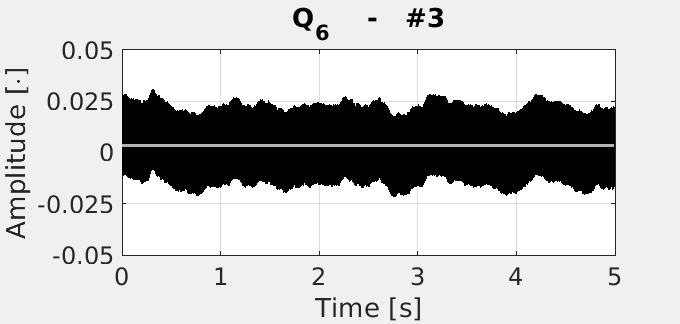

gains = zeros(7,3);
dcOffset = zeros(7,3);
for r = 1:3
    for m = 1:7
        %fileID = fopen('mic_0_num_0');
        fileID = fopen('num_'+string(r-1));
        data = fread(fileID,'single');
        data = data/(power(2,31)-1);
        
        onePacketLength = numSamples*numMics;
        numPacketsInData = floor(length(data)/onePacketLength);
        micData = zeros(numSamples,1);
        for i = 0:numPacketsInData-1
            micData = [micData; data(1+(micList(m)*numSamples)+i*onePacketLength:(micList(m)*numSamples)+i*onePacketLength+numSamples)];
        end
        micData = micData((numSamples+1)+round(2.5*fs):round(7.5*fs));
        dcOffset(m,r) = mean(micData);
        gains(m,r) = mean((micData).^2);%-dcOffset(m,r)


        colorList = ["r" "g" "b" "c" "m" "y" "k"];
        set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 11])
        plot(0:1/fs:(length(micData)-1)/fs,micData, "Color", colorList(m))
        hold on
        title('Q_' + string(m-1) + '    -   #' + string(r), 'FontSize', 22)
        xlabel('Time [s]', 'FontSize', 20)
        ylabel('Amplitude [\cdot]', 'FontSize', 20)
        
        if colorList(m) == "k"
            yline(dcOffset(m,r), 'LineWidth', 2, 'Color', 'w')
        else
            yline(dcOffset(m,r), 'LineWidth', 2)
        end
        grid
        ylim([-0.05 0.05])
        xlim([0 5])
        ytickList = linspace(-0.05,0.05,9);
        yticks(ytickList(1:2:end))
        yticklabels(string(ytickList(1:2:end)))
        xtickList = linspace(0,5,6);
        xticks(xtickList(1:1:end))
        xticklabels(string(xtickList(1:1:end)))
        ax = gca;
        ax.FontSize = 18;
        %legend('Output data', 'Mean')
        hold off
        exportgraphics(gcf,'post_mic_'+string(m-1)+'_num_'+string(r-1)+'.pdf')
    end
end


%hold off
gains

gains = 1.0e-03 *

    0.2231    0.2021    0.2205
    0.2016    0.1942    0.1966
    0.1921    0.1912    0.1905
    0.1914    0.1908    0.1898
    0.1974    0.1960    0.1909
    0.1902    0.1973    0.1844
    0.2338    0.2101    0.2021



mean(gains')

ans = 1.0e-03 *

    0.2152    0.1974    0.1912    0.1907    0.1948    0.1906    0.2154



max(mean(gains'))./mean(gains')

ans =     1.0006    1.0907    1.1261    1.1295    1.1057    1.1297    1.0000



normfactor = sqrt(max(mean(gains'))./mean(gains'))

normfactor =     1.0003    1.0444    1.0612    1.0628    1.0515    1.0629    1.0000


## Load everything

% fileID = fopen('mic_0_num_0');
% data = fread(fileID,'single');
% data = data/(power(2,31)-1);
% onePacketLength = numSamples*numMics 

onePacketLength = 1520

% numPacketsInData = floor(length(data)/onePacketLength)

numPacketsInData = 1755

% splitdata = zeros(numSamples,numMics);
% for i = 0:numPacketsInData-1
%     splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
% end
% splitdata = splitdata(numSamples+1:end,:)'

splitdata =     0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0002    0.0002    0.0001    0.0001    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0002
    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0048    0.0048    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0049    0.0048    0.0049    0.0049    0.0050    0.0048    0.0049    0.0049    0.0049    0.0050    0.0049    0.0049    0.0050    0.0049    0.0050    0.0050    0.0050    0.0051    0.0050    0.0050    0.0049    0.0049    0.0050    0.0